# Cognito_BDF_QuickView.m

Created 9/26/2018: Kristin Sellers

% Input: .bdf raw recording
%
% Output: Figures of spectrograms and spectrum

% Notes: Creates quick view of potential entrainability for uncleaned or
% partially cleaned data. Will look at data period from beginning of
% recording to 'stop' trigger (F2 == 511)

% revision 11/20/2018: Svjetlana Miocinovic
     % PSD calculated using pwelch and 0.5Hz freq resolution
     % added threshold method to determine if entrainment present (from Cognito_Spectra_V1.m and Cognito_DetermineEntrainability.m)
     % change data writing to csv file (instead of xls)
% revision 3/5/2019: Svjetlana Miocinovic
     % added 'average' montage (Biosemi data is acquired reference-free)
% revision 4/11/2019: Svjetlana Miocinovic
     % fixed eegplot channel labels display

clear all
close all
clc

User selections: Artifact rejection / preprocessing

stim_freq = 40; %Flicker stimulus frequency in Hz (20 or 40)
manualTimeRejection = 1; % 0 = no, 1 = yes
bandpassFilter = 1; % 0 = no, 1 = yes
bandpassFilterRange = [1 100]; % Must select if bandpassFilter == 1
programmedStopCode = 767; % 767 Corresponds to key F2; set to 0 to ignore trigger

Select file to process

[fileName, pathName] = uigetfile({'*.bdf;*.txt'},'Select raw data file','MultiSelect','off');
EEG = pop_biosig([pathName fileName]);

Reading data in BDF format...


eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames
         To extract events, use menu File > Import Event Info > From data channel


Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is C:\Users\mattokaren3\eeg_options.m


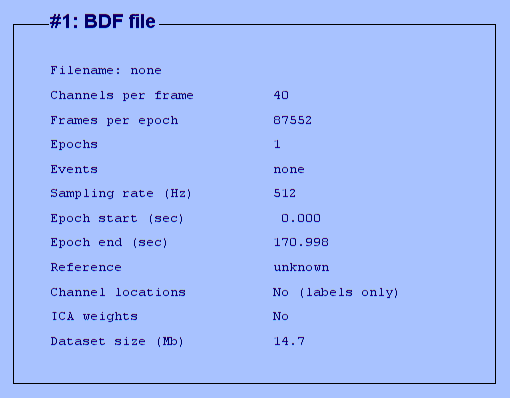

Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "BDFimport" v1.10 (see >> help eegplugin_bdfimport)
EEGLAB: adding "Biosig" to the path; subfolders (if any) might be missing from the path
EEGLAB: adding "ICLabel" v1.2.4 (see >> help eegplugin_iclabel) - new version 1.1 available
EEGLAB: adding "clean_rawdata" v2.0 (see >> help eegplugin_clean_rawdata) - new version 2.1 available
EEGLAB: adding "dipfit" v3.3 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt) - new version 2.3 available


EEG = eeg_checkset(EEG);
eeglab redraw


% Create figures subfolder
if exist( [pathName 'QuickView_Figures'],'dir') == 0
    mkdir([pathName 'QuickView_Figures'])
end

% Extract channels info
chanlocs = EEG.chanlocs(1:64);

Index exceeds the number of array elements (40).

Fs = EEG.srate;

User dialog box to set parameters

list = {'All channels','Entrainability: Visual','Entrainability: Auditory','Entrainability: Combined',};
[selectedItem,selection] = listdlg('PromptString','Select which channels to plot',...
    'SelectionMode','single','ListString',list);

chanLabels = extractfield(chanlocs, 'labels');

switch selectedItem
    case 1 % All channels
        chansToPlot = chanLabels;
    case 2 % Entrainability: Visual
        chansToPlot = {'P2','P4','P6','P8','P10','O2','PO4','PO8','P1','P3',...
            'P5','P7','P9','O1','PO3','PO7'};
    case 3 % Entrainability: Auditory
        chansToPlot = {'C4','T8','CP6','P4','P8','FC4','C6','CP4','P6',...
            'TP8','T7','C3','CP5','P7','P3','FC3','C5',...
            'CP3','P5','TP7'};
    case 4 % Entrainability: Combined
        chansToPlot = {'P4','P8','O2','P2','P6','P9','PO4','PO8','C4',...
            'T8','CP6','FC4','C6','CP4','TP8','P7','P3','P10','O1','P5','P1','PO3',...
            'PO7','T7','C3','CP5','FC3','C5','CP3','TP7'};
end

% Determine channel indices for select channels
if selectedItem ~= 1
    selectChans = find(ismember(chanLabels,chansToPlot)); %not in same order as chansToPlot so do not use chansToPlot later
else  %all channels
    selectChans = 1:length(chanlocs);
end

setParameters = 1; % 0 or 1; for spectrogram parameters

% Determine if stop code exists
for iEvent = 1:length(EEG.event)
    if  EEG.event(iEvent).type == programmedStopCode
        stimStopSample = EEG.event(iEvent).latency;
        break
    else
        stimStopSample = [];
    end
end

% Notch filter
[EEG, com, b ] = pop_eegfiltnew(EEG, 59, 61,[],1);
[ALLEEG, EEG, CURRENTSET] = pop_newset(ALLEEG, EEG, CURRENTSET,'setname',...
    '60Hz Removed Data');
EEG = eeg_checkset(EEG);
eeglab redraw

if bandpassFilter == 1
    % Bandpass filter
    [EEG, com, b ] = pop_eegfiltnew(EEG, bandpassFilterRange(1), bandpassFilterRange(2));
    % [EEG, com, b ] = pop_eegfiltnew(EEG, bandpassFilterRange(1), bandpassFilterRange(2),[],[],[],[],[],[]);
    [ALLEEG, EEG, CURRENTSET] = pop_newset(ALLEEG, EEG, CURRENTSET,'setname',...
        'BP Filtered Data');
    EEG = eeg_checkset(EEG);
    eeglab redraw
end

% Subtract average from all channels (remove DC offset)
EEG = pop_rmbase(EEG);
[ALLEEG, EEG, CURRENTSET] = pop_newset(ALLEEG, EEG, CURRENTSET,'setname',...
    'DC offset removed');
EEG = eeg_checkset(EEG);
eeglab redraw

% If stop code exists, extract only data during stim
if ~isempty(stimStopSample)
    selectData = EEG.data(1:length(chanlocs),1:stimStopSample);
else
    selectData = EEG.data(1:length(chanlocs),:);
end

%set 'average' montage (Biosemi data is acquired reference-free)
avg_signal = mean(selectData); 
for i = 1:size(selectData,1)
	selectData(i,:) = selectData(i,:) - avg_signal;    
end  

cleanedData = selectData;
if manualTimeRejection == 1

Manually select bad periods of data

    rejCommand = [...
        'tempMarkedRejection = [];'...
        'if ~isempty(TMPREJ),'...
        'tempMarkedRejection  = eegplot2event(TMPREJ, -1);'...
        'end;'...
        ];
    
    TMPREJ = [];
    tempMarkedRejection = [];
    eegplot(selectData,'eloc_file',EEG.chanlocs(1:64),'srate',Fs,'winlength',20,'wincolor',[1 0 0],'command',rejCommand,...
        'title','Select data segments to remove');
    uiwait
    
    cleanedData = selectData;
    
    if ~exist('tempMarkedRejection','var')
        tempMarkedRejection = [];
    end
    % Need to sort rejectionTimes so they are early to late
    rejectionTimes = sortrows(tempMarkedRejection);
    
    if ~isempty(tempMarkedRejection)
        for iRejection = size(rejectionTimes,1):-1:1
            cleanedData(:,rejectionTimes(iRejection,3):rejectionTimes(iRejection,4)) = [];
        end
    end
end

if (stim_freq == 40)
    thresholdBandFreqs = [35 45]; % Frequencies to use for normalizing peak power WAS [30 50]
    thresholdBandFreqs_exclude = [39 41]; % Frequencies to exclude from band for normalizing peak power
elseif (stim_freq == 20)
    thresholdBandFreqs = [10 30]; % Frequencies to use for normalizing peak power
    thresholdBandFreqs_exclude = [19 21]; % Frequencies to exclude from band for normalizing peak power
else
    error('Set stim_freq to 40Hz or 20Hz')
end    
    
for iChan = 1:length(selectChans)
    clear ch_data PSD 
    currentChan = selectChans(iChan);
    ch_data = cleanedData(currentChan,:);

Calculate spectrogram

    freq_mult = round(Fs/(0.5*128)); %0.5Hz freq resolution
    window = freq_mult*128;
    nooverlap = freq_mult*64;
    nfft = freq_mult*128;

%     window = 2*Fs*5;
%     nooverlap = window/2;
%     nfft = Fs;
    
    if setParameters == 0
        [S,F,T,PSD] = spectrogram(ch_data,[],[],[],Fs);
    elseif setParameters == 1
        [S,F,T,PSD] = spectrogram(ch_data,window,nooverlap,nfft,Fs);
    end

    %plot spectrogram and PSD
    figure
    clf
    set(gcf,'Position',[680 62 560 916])
    set(gcf,'PaperPositionMode','auto')
    set(gcf, 'PaperOrientation', 'landscape');
   
    % Plot 2D spectrogram
    subplot(3,1,1)
    imagesc(T,F,log10(PSD),[-2 2])
    set(gca,'Ydir','normal')
    xlabel('Time [s]')
    ylabel('Frequency [Hz]')
    h = colorbar;
    set(get(h,'title'),'string','Log Power');
    ylim([0 100]); 
    title('Spectrogram')
    
    % Calculate spectral density estimate using pwelch
	%[power2,freqs2] = pwelch(ch_data,[],[],Fs*2,Fs);
    [power,freqs] = pwelch(ch_data,window,nooverlap,nfft,Fs);
            
	gammaFreqs_temp = intersect(find(freqs >= thresholdBandFreqs(1)), find(freqs <= thresholdBandFreqs(2)));
	freqsToRemove = intersect(find(freqs >= thresholdBandFreqs_exclude(1)), find(freqs <= thresholdBandFreqs_exclude(2)));
	gammaFreqs = setdiff(gammaFreqs_temp,freqsToRemove);
            
	gammaMean = nanmean(power(gammaFreqs));
	gammaStdev = nanstd(power(gammaFreqs));
            
	gammaThreshold1(iChan) = gammaMean + gammaStdev;
	gammaThreshold2(iChan) = gammaMean + (2*gammaStdev);
	gammaThreshold3(iChan) = gammaMean + (3*gammaStdev);
            
	subplot(3,1,2)
	plot(freqs,log10(power),'k')
	hold on
	xlim([0 70]) % WAS [0 50]
	xlabel('Frequency [Hz]')
	ylabel('LOG Power [\muV^2/Hz]')
	title('Full Spectrum')
                
	subplot(3,1,3)
	plot(freqs,power,'k')
	hold on
	line(thresholdBandFreqs,[gammaThreshold1(iChan) gammaThreshold1(iChan)],'Color','b')
	line(thresholdBandFreqs,[gammaThreshold2(iChan) gammaThreshold2(iChan)],'Color','g')
	line(thresholdBandFreqs,[gammaThreshold3(iChan) gammaThreshold3(iChan)],'Color','r')
	xlim(thresholdBandFreqs)
	xlabel('Frequency [Hz]')
	ylabel('Power [\muV^2/Hz]')
	title('Gamma Power')
	legend('Power Spectrum','Mean + 1*stdev','Mean + 2*stdev','Mean + 3*stdev')   

    suptitle(chanlocs(currentChan).labels)
    figureName =  [pathName 'QuickView_Figures' filesep fileName(1:end-4) '_' chanlocs(currentChan).labels '.png'];
    set(gcf,'PaperOrientation','portrait');
    print(gcf,figureName,'-dpng')
    
    % Find freq closest to stim_freq (usually 40Hz)
    [offsetFrom40, indexNear40] = min(abs(freqs - stim_freq));
    power40Hz(iChan) = nanmean(power(indexNear40));
            
    allPower(iChan,:) = power;
end

%%determine entrainability for all selected channels
selectThreshold = 3; % 1 = 1 stdev above the mean; 2 = 2 stdev above the mean; 3 = 3 stdev above the mean

% For each channel, calculate difference between thresholds and 40Hz peak
powerDiffs_threshold1 = power40Hz - gammaThreshold1;
powerDiffs_threshold2 = power40Hz - gammaThreshold2;
powerDiffs_threshold3 = power40Hz - gammaThreshold3;
        
% Find channels with peak greater than threshold 3
aboveThreshold3 = find(powerDiffs_threshold3 > 0 );
% Find channels with peak above threshold 2 and below threshold 3
aboveThreshold2 = setdiff((find(powerDiffs_threshold2 > 0 )), aboveThreshold3);
% Find channels with peak above threshold 1 and below threshold 2
aboveThreshold1 = setdiff((find(powerDiffs_threshold1 > 0 )), [aboveThreshold3 aboveThreshold2]);
% Find channels with peak below threshold 1
belowThreshold1 = setdiff(1:length(selectChans), [aboveThreshold3 aboveThreshold2 aboveThreshold1]);
        
if sum([length(aboveThreshold3),length(aboveThreshold2),length(aboveThreshold1),length(belowThreshold1)]) ~= length(selectChans)
	error('Not all channels accounted when assigning to threshold categories')
end
        
switch selectThreshold
	case 1
    	thresholdToTest = gammaThreshold1;
	case 2
    	thresholdToTest = gammaThreshold2;
	case 3
    	thresholdToTest = gammaThreshold3;
end
aboveThresholdIndices = find(power40Hz > thresholdToTest);

chansAboveThreshold = [];
for iChan = 1:length(aboveThresholdIndices)
	chansAboveThreshold{iChan} = chanLabels{selectChans(aboveThresholdIndices(iChan))};
end
        
        
% Print to command window the channels above threshold
disp(['Channels above threshold: '; chansAboveThreshold(:)])
disp([ num2str(length(chansAboveThreshold)) ' channels above threshold out of ' num2str(length(selectChans)) ' total channels (' fileName ')'])

% Save .csv
aboveThreshold = power40Hz - thresholdToTest;
entrainabilityBinary = zeros(1,length(chanlocs));
entrainabilityBinary(aboveThresholdIndices) = 1;
    
dataToSave = {}; 
dataToSave{1,1} = 'Channel';
dataToSave{1,2} = 'Threshold';
dataToSave{1,3} = 'Stim_freq_Power';
dataToSave{1,4} = 'Entrainable';
dataToSave{1,5} = 'Above_Threshold';
    
for iChan = 1:length(selectChans)
	dataToSave{iChan + 1,1} = chanLabels{selectChans(iChan)};
	dataToSave{iChan + 1,2} = thresholdToTest(iChan);
	dataToSave{iChan + 1,3} = power40Hz(iChan);
	dataToSave{iChan + 1,4} = entrainabilityBinary(iChan);
	dataToSave{iChan + 1,5} = aboveThreshold(iChan);
end
    
dataToSave_table = cell2table(dataToSave(2:end,:));
dataToSave_table.Properties.VariableNames = dataToSave(1,:);

myFileName = [pathName fileName(1:end-4) '_Entrainability.csv']; %WAS .xslx
if exist(myFileName, 'file')
    disp('Deleting existing analysis file')
    delete(myFileName); %delete existing file since xlswrite will not overwrite it
end
%xlswrite(myFileName, dataToSave) %sometimes fails randomly
writetable(dataToSave_table,myFileName)